# Lab #4 Sensor Noise and Quantization Noise Measurements (Two Weeks)

### **Note: This is the updated MLX file from MyCourses.**

## Objectives:

- Learn how to create uniformly distributed random numbers.

- Learn how to characterize a signal’s probability distribution using MATLAB histogram tools.

- Measure the noise from a sensor using Analog to Digital Converter (ADC) readings.

- Learn how to create a Digital to Analog Converter (DAC) to source a dithering voltage.

- Apply dithering and oversampling and averaging to reduce quantization noise and increase Signal to Noise Ratio (SNR).

- Characterize a measurement system’s SNR, precision and accuracy.

## Reading

    Review Chapters 2 & 3 in Smith.        

    AVR 120 – Atmel ADC characterization app note

    AVR 121 – Atmel dithering app note

## Intended Learning Outcomes

- Demonstrate the use of dithering noise and averaging to increase the signal to noise ratio of a measurement system.

- Utilize typical error formula to compute equivalent number of bits of ADC resolution after dithering and averaging. 

## Lab 4 Arduino Code Base

The code base for this lab can be found in myCourses under the section for this lab.

### SECTION 1a – Assessing sensor noise, accuracy, and signal to noise ratio (SNR)

### Overview

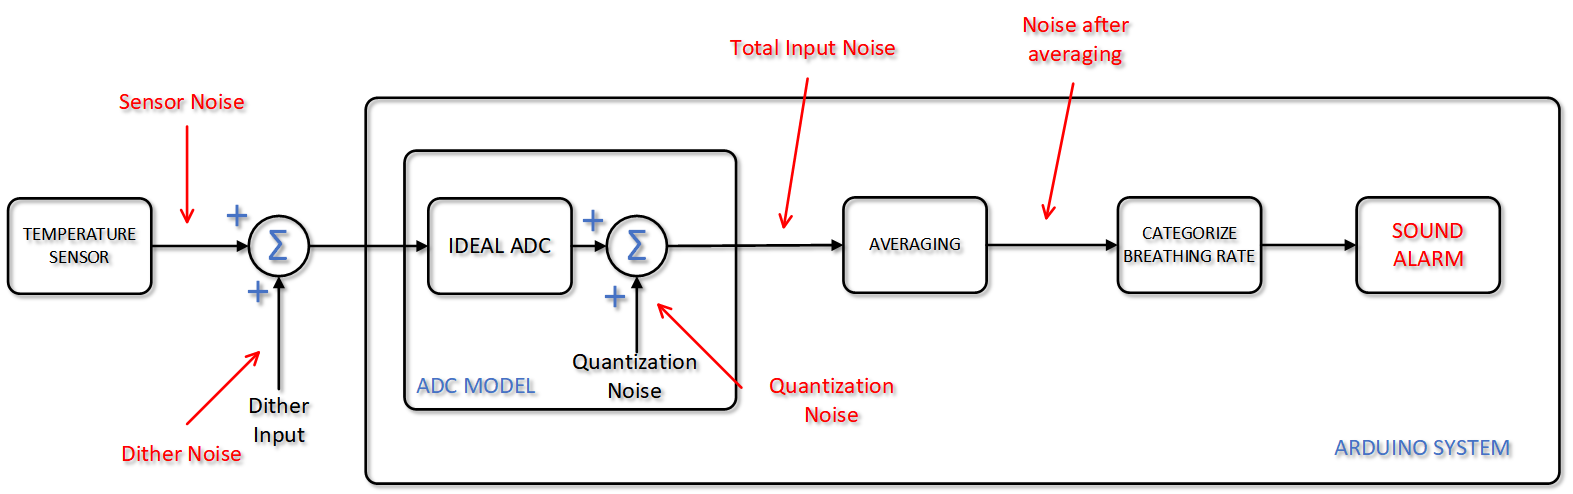

Sampled measurement noise is the sum of the analog sensor noise and ADC quantization noise.  The standard deviation of quantization noise is 0.29 Code Values (CV) assuming that quantization error is uniformly distributed over +/- 0.5 LSB.

In this section you will estimate the standard deviation of the sensor noise alone by observing the amount of ADC value “chatter” as the temperature drifts through the quantization level thresholds

As the temperature drifts lower, the value of the sensor passes through multiple quantization levels of the ADC.  The sensor has some amount of noise on its output voltage.  We can view this as a mean value with some added noise with a peak to peak value.

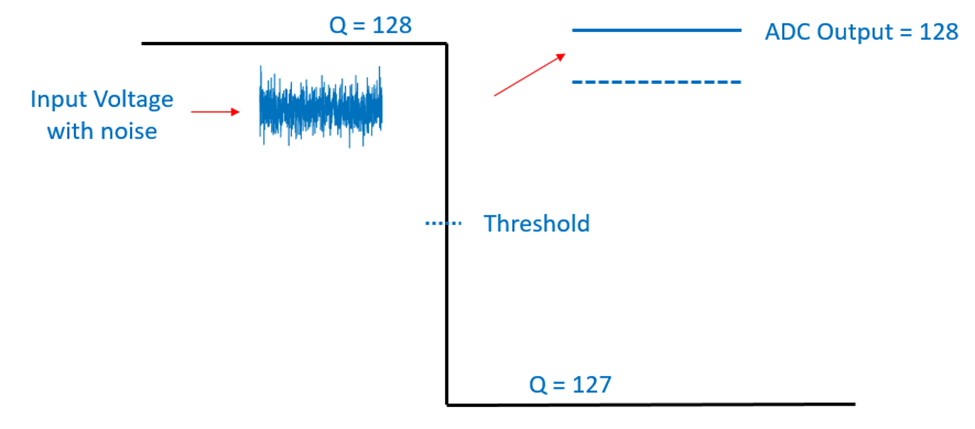

The ADC will round the incoming voltage to the nearest quantization value.  The threshold location is centered in between each quantization level.  If the input signal is crossing back and forth across that threshold then the output will toggle back and forth or "chatter" between two values.

 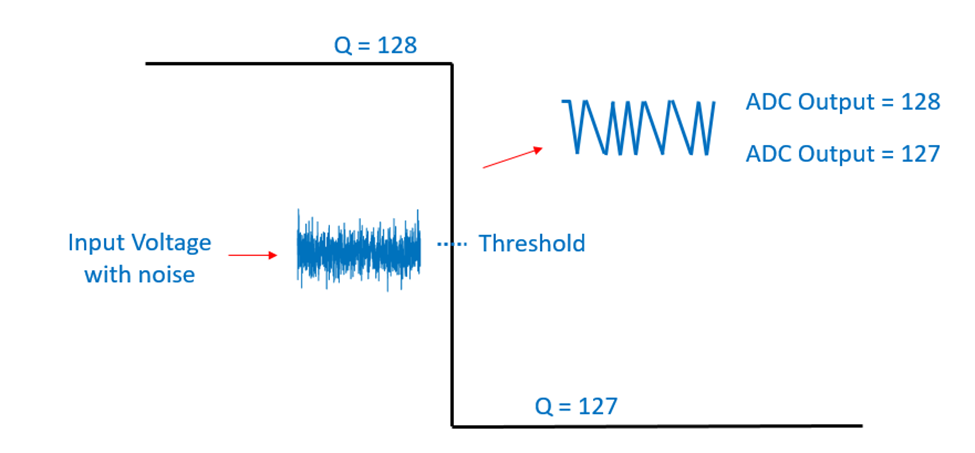

Zero mean noise is centered on the sensor signal.  When the signal is centered on a conversion threshold, the noise will drive the input above and below that threshold and induce output chatter.  When the signal drifts 3 sigma away from a threshold, chatter effectively stops because the peaks of the signal no longer cross the threshold.  The total width of the chatter pattern measured in samples is approximately 6 times the standard deviation of the sensor noise.  This is because the peak to peak value of normally distributed random noise is approximately 6 times the standard deviation.  

The distance between the start of the "chatter" noise clusters gives us an idea of how large a single bit is in the units of samples.  Yes, samples is a weird unit to relate to voltage, but if the signal is drifting at a constant rate, that is a constant change in voltage per unit time of a sample then we can relate the number of samples between "chatter" clusters to the voltage change between them.  The width of the "chatter" or our measure of the peak to peak value of the "chatter" will also be in samples.

By observing the width of a chatter pattern at a particular code value relative to the spacing between chatter patterns of adjacent code values, we can infer the width of the sensor noise distribution relative to a code value or LSB..

The distance between the clusters of “chatter” reflects the size of each bit.  The width of the chatter reflects the peak to peak value of the noise.  

The standard deviation of the noise in units of samples can be estimated to be  $\sigma_{samples}=\frac{\text{chatter width}}{6} $                       

Then the distance between clusters of “chatter” can be used to convert the standard deviation in samples to the standard deviation relative to a code value:     

#### 
$$\sigma_{sensor}=\frac{\sigma_{samples}}{distance}$$


###  **Procedure:**

Connect the temperature sensor in the same manner as in Lab 1. That is, power the LM61 with +5V and GND, and connect the output to Arduino A0.  Again, I can't emphasize enough how important it is to properly connect the temperature sensor to make the system work.

Upload the sketch code for the Lab 4 Code base, fix any errors.  Start MATLAB from a directory where you can access the “CaptureArduinoData.m”, “ArduinoSerial.m” and “ActivePlot.m” scripts. In the command window of MATLAB pre-type the command to run the CaptureArduinoData using the correct COM Port.  Don’t hit enter yet.

 

#### Here is a copyable string

#### data = CaptureArduinoData('ComPort',3,'BaudRate',115200,'NumActivePlots',1);

Pinch the sensor for about 6 to 10 seconds.  Release.  You may put the sensor in a container (plastic bag, for example) to protect it from air currents but this isn't absolutely necessary.  Begin data collection by hitting Enter in MATLAB after the command line shown above.

Adjust your data collection technique until you obtain a section of samples that looks something like the data in Figure 3. Try to get a few clusters of “chatter” that are reasonably wide so that you can make a good estimate. Typically there will be more “chatter” when the signal is drifting slowly.  So you may have to adjust your start time and the number of samples collected to get a good data set.

When you have data that has several sections of chatter similar to the graph below, save the data in a file with a descriptive name.  In the code section below, modify and add code to load the file and plot your data. 

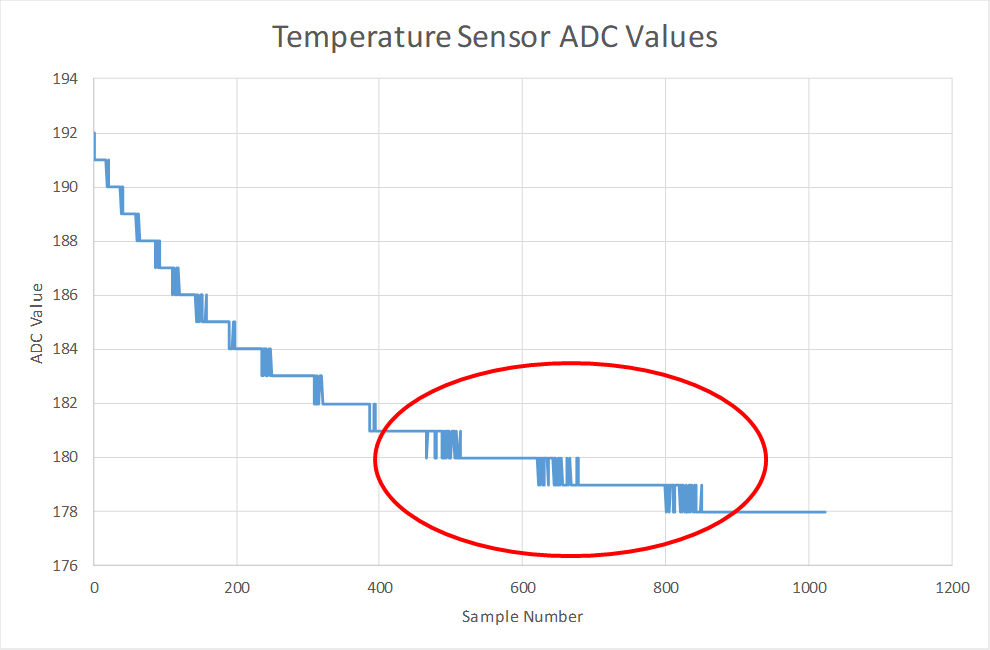

#### Figure 4 -- Example of Good Chatter Noise

Load in the data file that you saved when pinching the LM61 temperature sensor.  When loading the file, a variable named **outData** will be placed into the MATLAB workspace.  The variable outData is a variable with multiple columns, the first column is the sample number, the remaining columns are the other values that you saved.

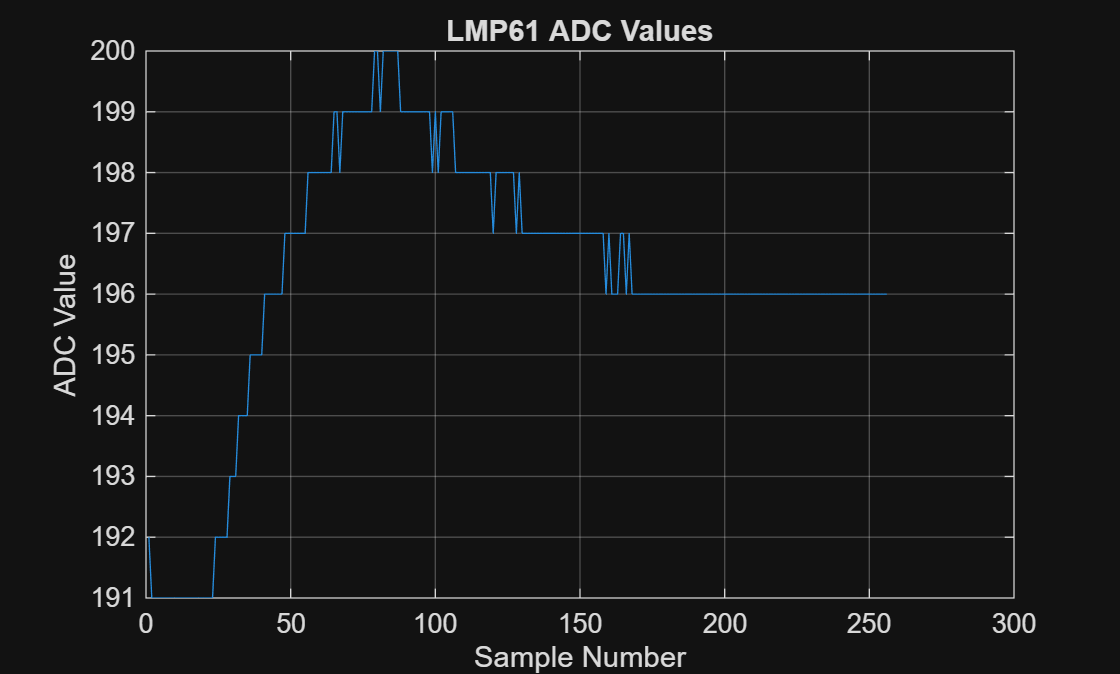

fName = '1a.mat';
load( fName );

%  Plot the data for the Pinch test.  Add appropriate titles and x and y
%  axis labels.  The file will load a matrix outData into the worspace.

% SOLUTION
figure;
plot(outData(2:end, 1), outData(2:end, 2));
grid on;
title("LMP61 ADC Values");
xlabel("Sample Number");
ylabel("ADC Value");
hold off;

## Estimate sensor noise

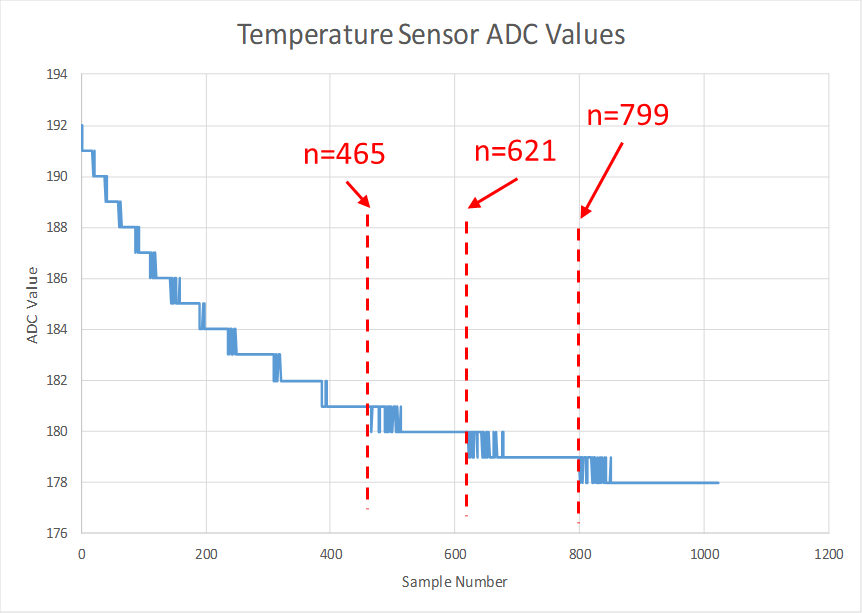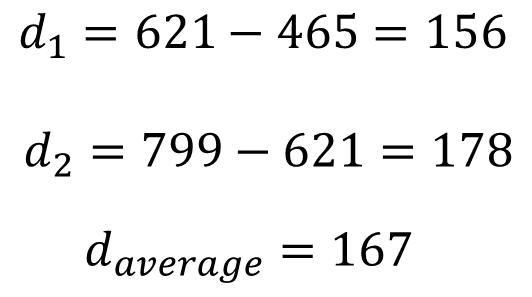

#### Figure 5 -- Estimating Distance Between Chatter "Bursts"

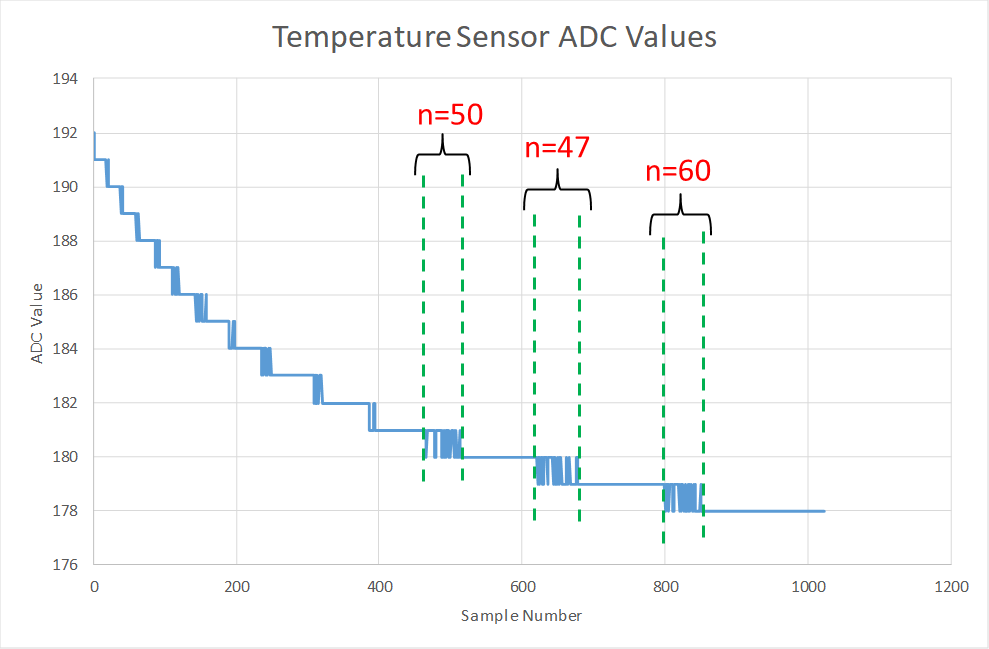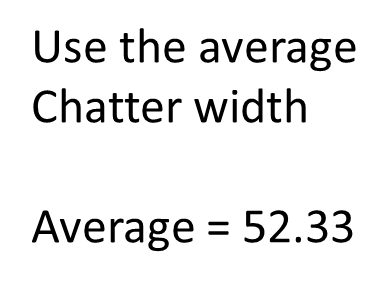

#### Figure 6 -- Estimating Chatter Width

For the example data, the average spacing between the three chatter clusters d is around 167 samples and the average width of the chatter group is around 52.3 samples.  We interpret this to mean that the Gaussian distribution of sensor noise has a standard deviation of 

#### 
$$\sigma_{sensor} = \frac{width_{avg}}{6}\times\frac{1}{dist_{avg}}$$


#### 
$$\sigma_{sensor}=\frac{52.3}{6}\times \frac{1}{167}=0.0522$$


The sensor has a standard deviation of  approximately 0.0522 of each code value (CV).  We are working in code values here not volts because we have saved the ADC output where each count is a code value.  We know that the standard deviation of the noise due to quantization is 0.29 times one code value.  The total measurement noise that is seen at the output of the ADC includes the sensor noise and the ADC quantization noise.  Its value is then found by adding the two standard deviations in quadrature.  Again the units here are code values.

#### 
$$\sigma_{total} = \sqrt{\sigma_{sensor}^2+\sigma_{quant}^2}=\sqrt{0.0522^2+0.29^2}=0.2947\approx\sigma_{quant}$$


Select a segment of the data that looks like the data in Figure 4 above with at least three chatter bursts.  Create a variable from the segment of Pinch Data that you chose to measure the chatter width and distance between chatter. Make a plot of that segment.  Use the MATLAB colon operator to grab just the desired segment of the data.  An example is shown below.

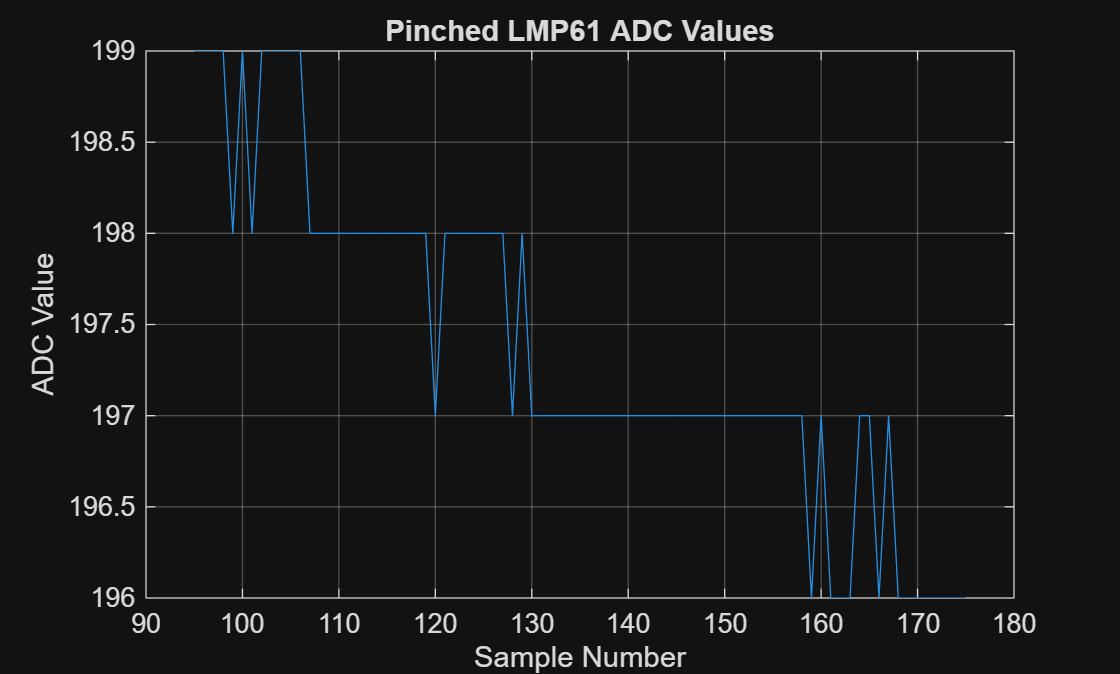

% Select a segment from your pinch data and create a new variable
%
% pinchSegment = outData( startSample:stopSample,:)
%
%  The first argument startSample:stopSample indicates the rows to choose.
%  The second argument, just the colon indicates "give me all the columns".
%  
%  Plot the data segment

%  SOLUTION -- Plot the Segment Data

% Note to team: Y'all will need to modify the two values below for the newly collected data.
pinchStart =  95;
pinchEnd   = 175;

pinchSamples = outData(pinchStart + 1:pinchEnd + 1, 1);
pinchValues  = outData(pinchStart + 1:pinchEnd + 1, 2);

figure;
plot(pinchSamples, pinchValues);
grid on;
title("Pinched LMP61 ADC Values");
xlabel("Sample Number");
ylabel("ADC Value");
hold off;

Measure the approximate distance between the beginning of each burst (you can average them) and measure the width of each burst (again you can average the three values).  You can use data tips in the graphs to measure the values.  Its helpful to undock the figure from the live editor.  Do that by hovering over the graph tools in the upper right corner of the graph and pressing the "Open in figure window" button

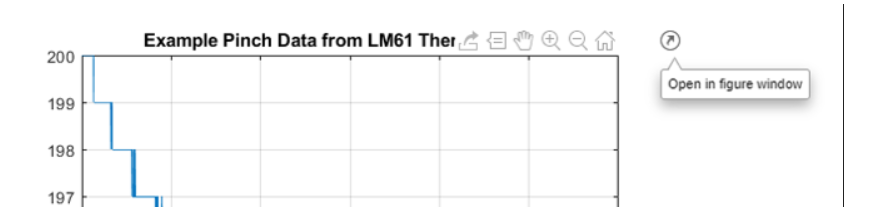

#### Figure 7 -- Opening Figure in a New Window

Once you have the graph in a figure window you can hover over the graph control buttons and select Data Tips.  Here you can put multiple markers on your graph

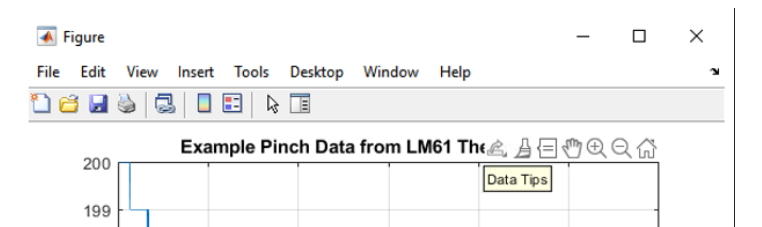

#### Figure 8 -- Selecting Data Tips

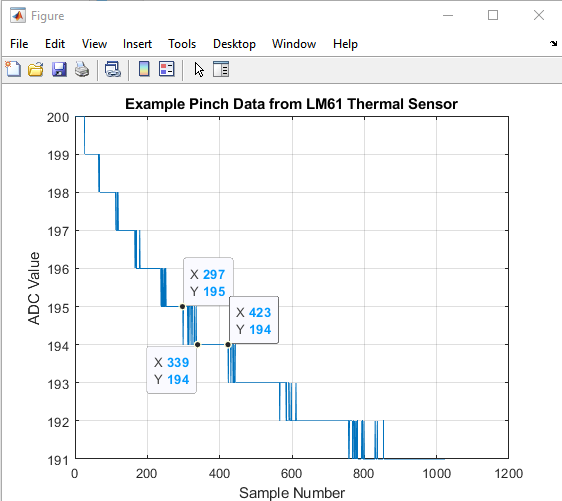

#### Figure 9 -- Place  Data tips on the graph data to measure width and distance

Using the width and the distance, estimate the standard deviation of the noise of the sensor using the formula below.  Enter these computations into the code section below.

Compute an estimate of the measurement noise using the formula:

#### 
$$\sigma_{samples}=\frac{width_{avg}}{6}$$


#### 
$$\sigma_{sensor}=\frac{\sigma_{samples}}{dist_{avg}}$$


Combining the equations

#### 
$$\sigma_{sensor} = \frac{width_{avg}}{6}\times\frac{1}{dist_{avg}}$$


%  Compute the sensor measurement noise standard deviation

%  widthChatter = 
%  distanceChatter = 

%  stdSamples = 

%  stdSensor = 

%  SOLUTION

% Note to team: Y'all will need to modify the two values below for the newly collected data.
widthChatter = 9;
distanceChatter = 12;

stdSamples = widthChatter / 6;
stdSensor = stdSamples / distanceChatter;

Compute the estimated total measurement noise by including the quantization noise

%  stdTotal = 

% SOLUTION
stdTotal = sqrt(stdSensor^2 + 0.29^2);

## Check the Estimate

To check this estimate we need to remove the temperature drift.  The temperature drift adds to the value of the variance.   From inspection, variance around drift due to quantization is much less than this.  As was done in Lab 1 eliminate the contribution of drift by fitting a linear line to the data to estimate it.  

Use just the segment of data that you used to estimate the sensor noise to estimate the drift.  Do not use the entire data set.  Use only a section that is approximately linear.

Review the approach from Lab 1.  

Use the “polyfit” function in MATLAB to generate a drift estimate.  Calculate the error between the estimate and the data by subtracting the drift estimate from the signal. An example is shown below.  The variance of this error is 0.31, which is very close to the estimate computed earlier (.2947).

Compute the standard deviation of the estimate of the error and compare it to the computation of the noise based on the chatter measurements.

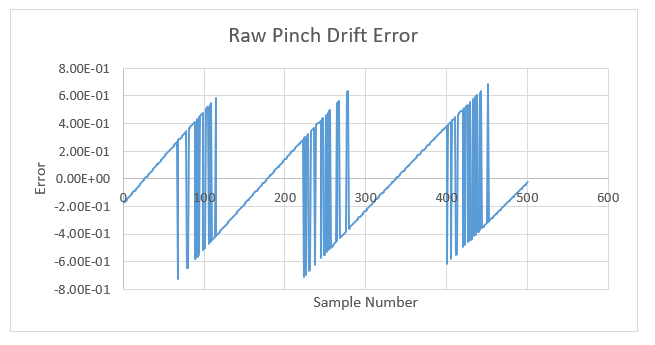

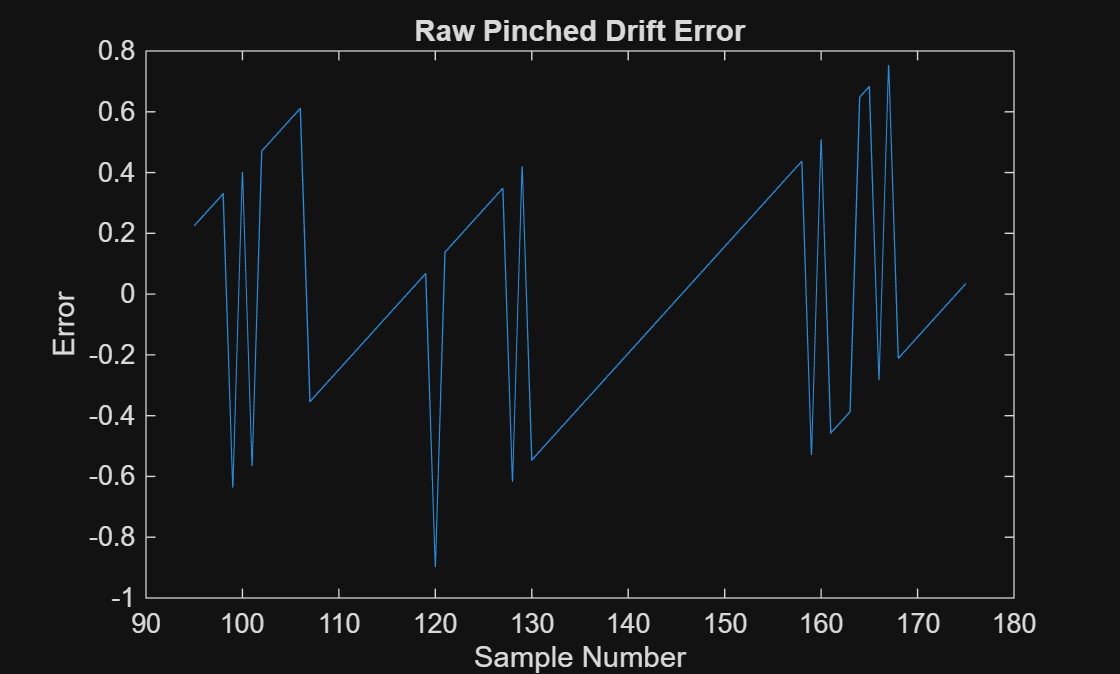

%  Estimate the temperature drift of the signal by fitting a curve through
%  your segment of data.
%
%  Use the MATLAB polyfit command.  You can try to use a linear fit (first
%  order) or a quadratic fit (second order).  This is an argument in the
%  polyfit function
%

%  coeffs = polyfit(  xData, yData, order )

%  Create an estimate of the drift and find the error by removing the drift estimate
%  from the pinch segment data.  Plot the error.

%  Compute the standard deviation of the error.

%  SOLUTION

coeffs = polyfit(pinchSamples, pinchValues, 1);
slope = coeffs(1);
intercept = coeffs(2);

drift = slope * pinchSamples + intercept;
error = pinchValues - drift;

figure;
plot(pinchSamples, error);
grid on;
title("Raw Pinched Drift Error");
xlabel("Sample Number");
ylabel("Error");
hold off;


%  Compute the standard deviation of the error

%  SOLUTION
stdError = std(error);


## **SECTION 1b – Oversample and Averaging to Reduce System Noise **

### **Overview**

A common technique used to reduce measurement noise is to oversample the data by a factor of N with respect to the required sample rate and report the average of the subsamples.  The standard deviation or typical error of oversampled and averaged samples is reduced by$\sqrt{N}
$ with respect to the standard deviation of the original data.  This is only true, however, if the measurement noise is visible in the data.  In the previous section there are large sample ranges of constant output that will not change when oversampled and averaged. Basically, averaging the same number over and over again does not change the number.  In this section, you will make oversampled and averaged measurements of temperature and calculate noise statistics from the data.

### **Procedure**

- In the code, uncomment the line setting the variable sample to the output of the `analogReadAve() function `so that line will be executed when run.  This code will oversample the data by a factor of 160.  Comment out the call to analogRead().  See the code snip below.

- Upload the program, fix any errors.  Capture data from a Pinch Test using MATLAB.

- Collect temperature data using the same method as before, Save the data as a MATLAB .mat file with a descriptive filename.

- Choose a section of the data for analysis.  Try to encompass 2 to 3 segments of the "stair step" results.

- Using MATLAB in the code section below fit the underlying temperature drift, calculate residual error and calculate its standard deviation.

- Include graphs of the data section you chose and the error.  Include the calculated standard deviation in your report.  Typical results are shown below.  Ideal typical error for 160x oversampled averaging is $\frac{0.29}{\sqrt{160}} = 0.02CV
$ .  The standard deviation of drift compensated error calculated from the example data shown above is 0.178 CV.

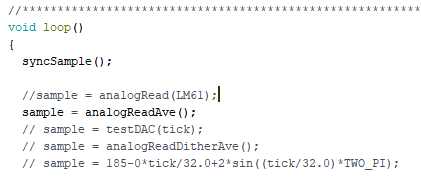

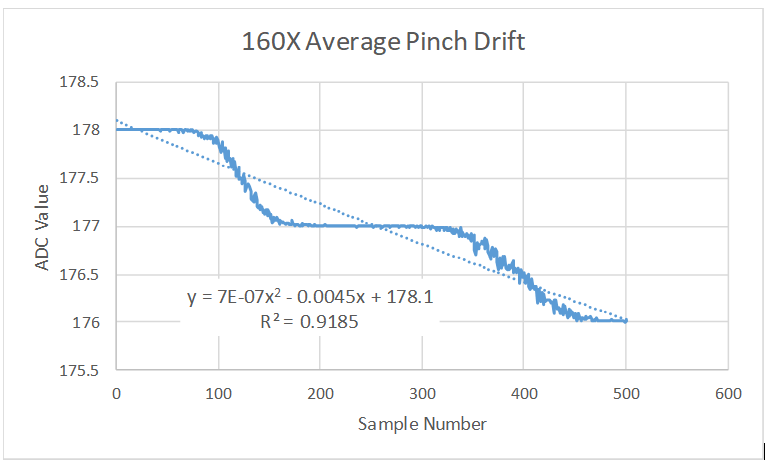

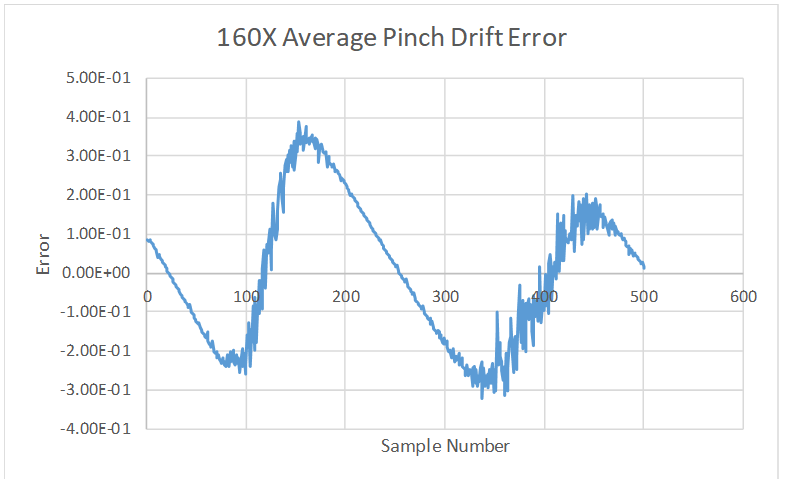

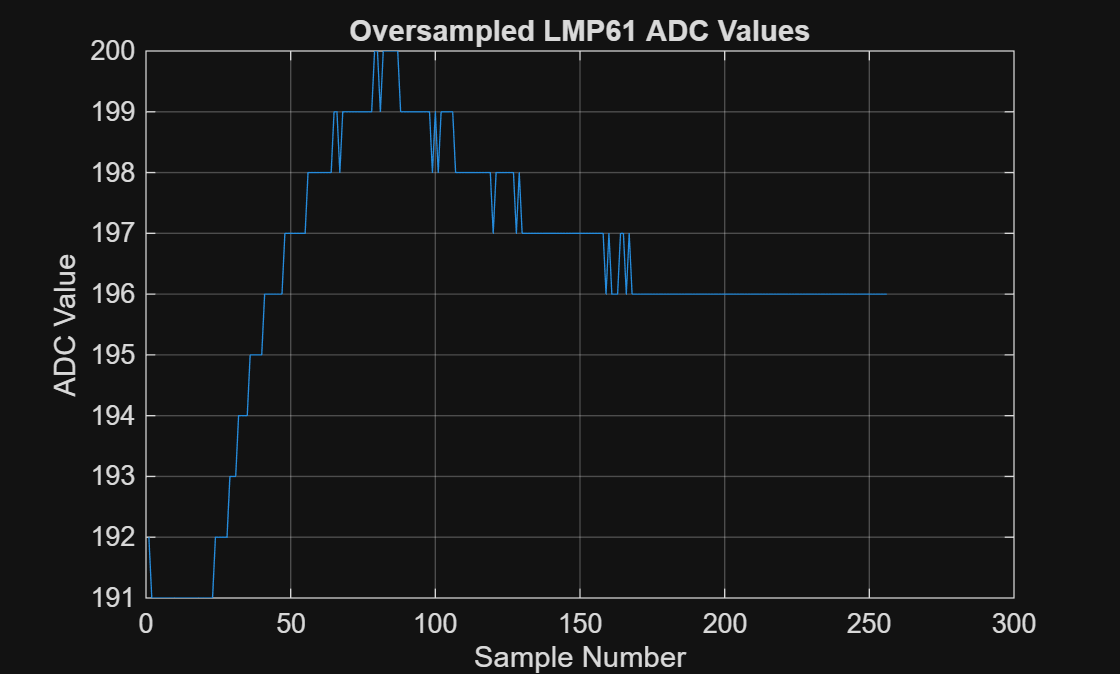

%  Capture another set of pinch data using oversampling and save the data in a file.
%  Load the file and plot the data
%
%  Estimate the temperature drift of the signal by fitting a curve through
%  a selected portion of the data.
%
%  Use the MATLAB polyfit command.  You can try to use a linear fit (first
%  order) or a quadratic fit (second order).  This is an argument in the
%  polyfit function
%

%  coeffs = polyfit(  xData, yData, order )

%  Create an estimate of the drift and find the error by removing the drift estimate
%  from the pinch segment data.  Plot the error.

%  Compute the standard deviation of the error.

%  SOLUTION
fName = '1b.mat';
load( fName );

figure;
plot(outData(2:end, 1), outData(2:end, 2));
grid on;
title("Oversampled LMP61 ADC Values");
xlabel("Sample Number");
ylabel("ADC Value");
hold off;

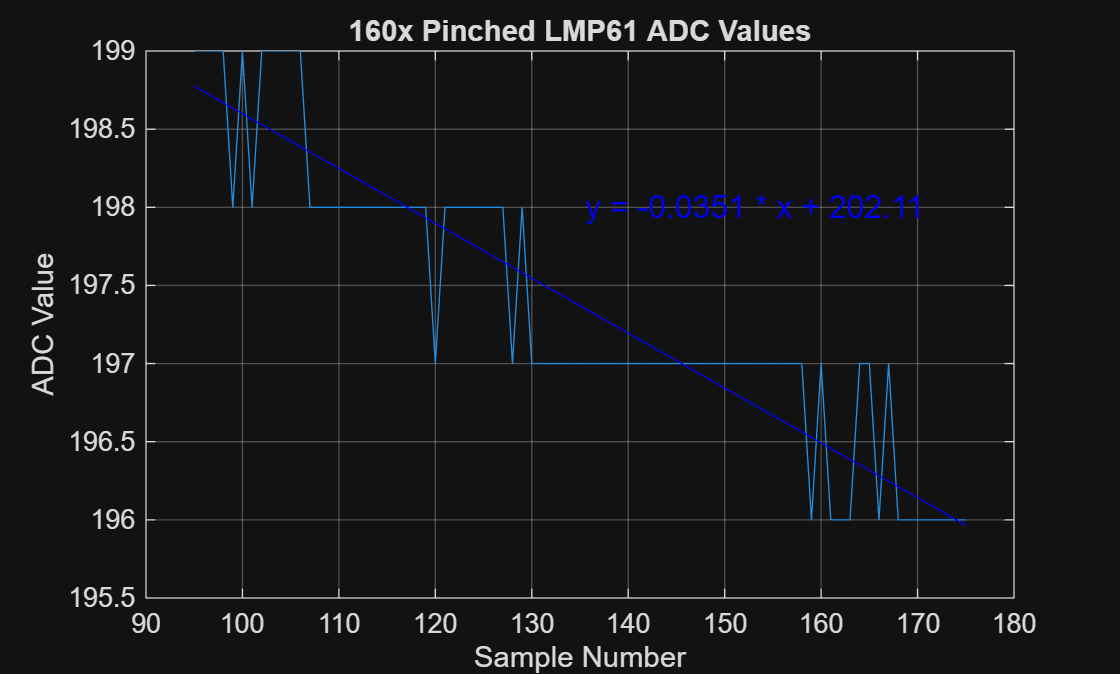


% Note to team: Y'all will need to modify the two values below for the newly collected data.
pinchStart =  95;
pinchEnd   = 175;

pinchSamples = outData(pinchStart + 1:pinchEnd + 1, 1);
pinchValues  = outData(pinchStart + 1:pinchEnd + 1, 2);

coeffs = polyfit(pinchSamples, pinchValues, 1);
slope = coeffs(1);
intercept = coeffs(2);

drift = slope * pinchSamples + intercept;
error = pinchValues - drift;

text1 = sprintf("y = %.4f * x + %.2f", slope, intercept);

figure;
plot(pinchSamples, pinchValues);
grid on;
%hold on;
%plot(pinchSamples, drift, "b-");
title("160x Pinched LMP61 ADC Values");
xlabel("Sample Number");
ylabel("ADC Value");
% Note to team: 198 is the y pos of the text and might need to by modified.
%text(pinchSamples(1, 1) + size(pinchSamples, 1)/2, 198, text1, "FontSize", 12, "Color", 'b');
hold off;

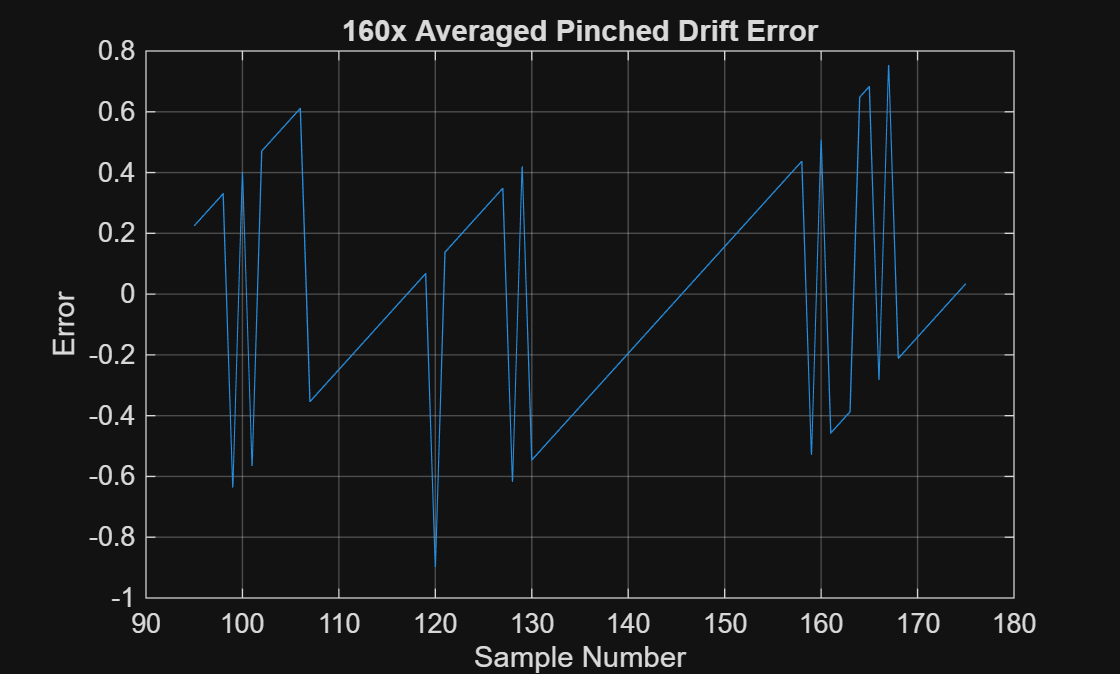


figure;
plot(pinchSamples, error);
title("160x Averaged Pinched Drift Error");
grid on;
xlabel("Sample Number");
ylabel("Error");
hold off;


%  Compute the standard deviation of the error estimate when using
%  oversampling and averaging (OSA)

% SOLUTION
stdErrorOSA = std(error)

stdErrorOSA = 0.3585

## **SECTION 1c – Adding Dithering Noise to Enable Oversampled Averaging **

### **Overview**

When the noise is small enough that quantization hides the noise oversample averaging is not effective. The somewhat counterintuitive solution is to add sufficiently large ‘dither’ noise to the sensor signal prior to ADC sampling.  Once the ADC output is noisy over the full sample range, oversample averaging is effective.  Due to dithering, the total noise that must be suppressed is larger than the sum of sensor and quantization noises, but an effective tool to suppress it is enabled.  Such is the cost of doing business.

### **Hardware Description**

The DAC hardware setup is shown in the following schematic, with construction advice in the accompanying pictures.  Arduino pins 5, 4, and 3 (DAC2, DAC1, DAC0, respectively) are configured as digital outputs.  Each pin and its associated resistor acts as a switchable current source.  The effect of $R_{dith}$ on branch current is negligible due to its small value relative to branch resistances.  Branch currents are binary weighted and summed as they pass through .  DAC(2..0) = 001 impresses a  voltage of 50*(5V / 200K) = 1.25 mV.  DAC(2..0) = 111 induces a   of approximately 5.0mV + 2.5mV + 1.25mV = 8.75 mV.  Eight DAC codes are available based on the three bits.

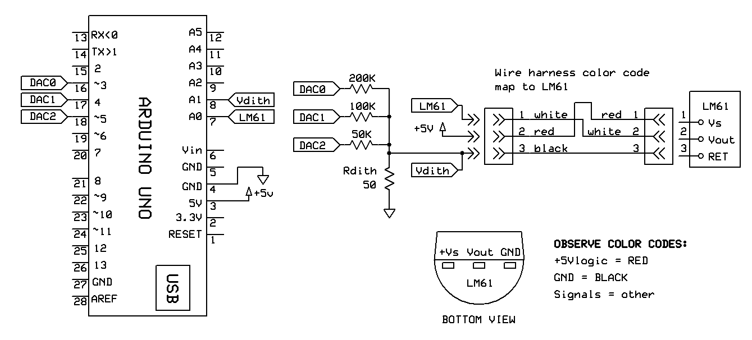

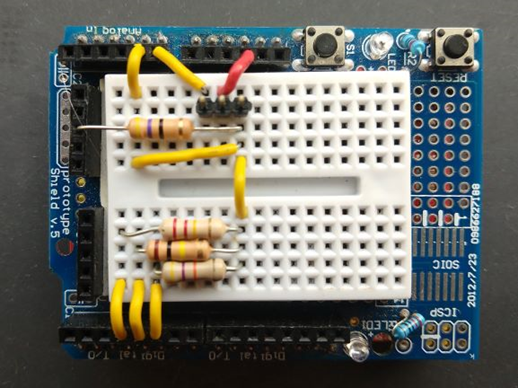

## **Code Description: Hardware Testing**

The first order of business is to test the DAC.  Because the dither voltage is so small with respect to the ADC LSB we cannot make a direct measurement.  Temporarily replace the 50 ohms of  $R_{dith}$ with 2.2K.  This raises the peak DAC voltage to around 385 mV, or 75 code values, which enables meaningful ADC measurements.  Connect the output of the DAC on $R_{dith}$ to the A1 input of the ADC.

Note in the `testDAC()`function that the lowest three bits of the sample counter tick are decoded by bit masking and driving the DAC[2..0] output pins/binary weighted current sources.  Each iteration of the `loop()` function advances the DAC a single step through its modulo seven cycle, creating a ramp voltage on $R_{dith}$**.**

## **Procedure:**

- Build the DAC circuit on your proto board.

- Uncomment the line asigning the varialbe sample to be the output of `testDAC(tick)`**. ** Upload the program, fix any errors, enter the command into MATLAB to capture data from the Arduino.

- Change the number of samples to collect to 256 by changing the global variable NUM_SAMPLES.

- Collect 256 samples of DAC voltage data, save the data and then plot a representative subset using MATLAB.

- Using MATLAB, generate and plot a histogram and the cumulative density function (cdf) of the samples. 

- Change the `testDAC()`call parameter to random(256). 

- Collect 256 samples of DAC voltage, save and plot the data and histogram.

- What is the typical error of the ramp data?  What is the typical error of the random data?

The tick variable driven voltage and histogram charts should resemble the (idealized) following.

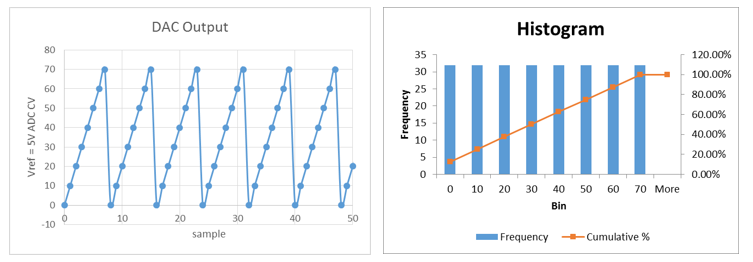

%  Plot the 256 samples of the DAC voltage data

%  Plot a histogram (both normal and cumulative) of the 256 sample data

%  Plot the data and historgrams after changing the call parameter to testDAC() to
%  random(256)

%  Compute the typcial error (standard deviation) of the ramp data

%  Compute the typcial error (standard deviation) of the random data

% SOLUTION




## **Dither Voltage Generator Hardware Description**

The DAC you built and tested in Section 1 can be used to inject dither noise into the temperature measurement.  The output signal of the LM61 is the difference between the Vout and RET (GND) pins of the device.  Applying a dither voltage to the RET pin with respect to the ground of the Arduino GND results in Vout being the sum of the temperature signal plus the dither voltage with respect to GND.  The amplitude of the dither signal can be adjusted by selecting $R_{dith}$.

Each sample reported is the average of 160 subsamples and each subsample is a reading of the LM61 output plus a dither value.  The average value of the dither is non-zero, but known, so its effect can be subtracted out of the data if desired.  The standard deviation of the dither noise is adjustable by choice of $R_{dith}$.  Dither should be as small as possible, but large enough to ensure noise in the ADC readings over all sample ranges.

## **Procedure**

- Change the circuit test value of $R_{dith}$ to approximately 50 ohms.  This is a good starting point for the system with ADC Vref = 5V and the typical noise level of the LM61.

- Complete the coding of the function `analogReadDitherAve() `by combining the functions of `analogReadAve()` and `testDAC()`. Each call of the function must also return the average of `NUM_SUBSAMPLES` subsamples of dithered LM61 output.

- Be sure to write a new value to the DAC each time that a new sample is read from the sensor.

- In the code, uncomment the line setting the value of the variable sample to `analogReadDitherAve()`.  Upload the program, fix any errors.  Run a pinch test capturing data in MATLAB.

- Fit underlying temperature drift, calculate residual error and calculate its standard deviation.  Plot the original data, and the signal with the drift removed.  Calculate the standard deviation of the signal with the drift removed. Plot a histogram of the noise.  Include these plots in your report.

- Compare the raw, oversample-averaged, and oversample-dither-averaged noise measures with one another and with theoretical expectations.  Apply the following noise calculations appropriately.

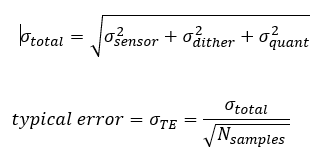

## **Note!**

You must scale the value of the $\sigma_{dither}$ because the resistor value in the circuit changed from $2.2K\Omega $   to $50\Omega$.  This lowers the output voltage and also impacts the standard deviation of the dither voltage.

Typical error is, in essence, the noise level in the estimate of the true mean, after averaging N subsamples.

%  Plot the data taken with the dither/averaging
%  Plot the signal with the drift removed
%  Plot a histogram of the signal with drift removed both the PMF and the CDF.
%  Compute the standard deviation of the signal with drift removed.

%SOLUTION





%  Compute values for Table 1

%  SOLUTION


%  OSA only case



%  Dither and OSA case




# Table 1 -- Sensor Noise Levels for Different Processing Methods

Table 1 is the key result from this lab experience.  Be careful to understand each input to the table and what is its importance and what it means.

Complete the table and include it in your report.  Here are the definitions of the quantity values.  A block diagram of the noise values and their location in the circuit is shown below

1 CV Signal -- One code value or 1.0 for all methods.

Sensor Noise SD -- The standard deviation of the sensor noise that you estimated in section 1a.

Quantization noise  SD -- The standard deviation of the quantization noise based on CV = 1.

Dither Noise SD --- The standard deviation of the noise added by dither estimated in section 1c scaled by the resistor scale from 2.2K to 50 ohms.

Total Input Noise SD -- The theoretical standard deviation of the sum of the sensor, quantization and dither noise sources.

Noise after averating (theoretical) -- The theoretical standard deviation after averaging 160 samples.

Noise after averaging (measured) -- The value that you computed for the standard deviation of the measured noise for each process

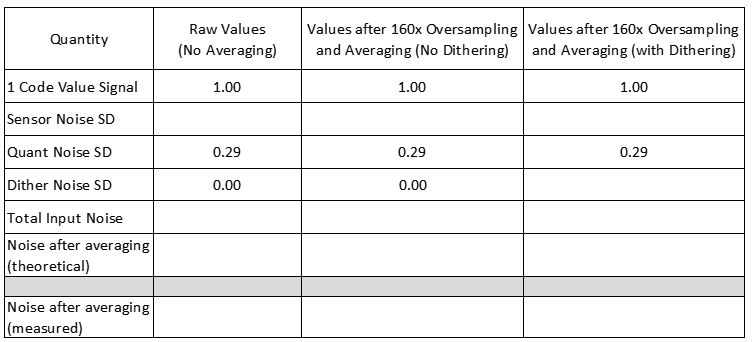

## **SECTION 1d – Effective ADC Bit Depth from Dithering Noise and Averaging**

By dithering and averaging, the noise level in the previous section was reduced from a quantization noise level of 0.29 LSB (least significant bits) to a significantly lower typical error.  One way of viewing this is that the ADC has increased *effective* resolution, i.e. it behaves as if it has more bits (e.g. 8 bit vs 10 bits vs 12 bits).

If we treat all of the noise as coming from quantization, how many effective bits does the ADC have now that we have added dithering noise and averaged subsamples?  Easy.  The standard deviation of the baseline sampling system is 0.29 LSB.  If the standard deviation of the processed (averaged or dither-averaged) samples is 8x smaller, the result could be ascribed to an 8x smaller LSB.  For a fixed Vref, this corresponds to an apparent additional 3 bits of ADC resolution (i.e. $2^3 = 8$).  The improvement ratio may not be an even power of 2.  If the improvement ratio is 9.67x, for example, then  $9.67 = 2^n$  or $n = 3.27$.  If the original system was 10 bits, the new system has performance better than one of 13 bits, but less than 14 bits.

Compute the increase in the effective resolution (in bits) of the ADC by using dithering and averaging

%  Compute the increase in the effective resolution (in bits) of the ADC by using dithering and averaging


%  SOLUTION



## **Report**

Write a concise report aiming for no more than 4 pages in IEEE format explaining the measurement problem and your solution.  Its ok to go over 4 pages, but try to keep it concise.  Detail should be suitable to enable a DSP student familiar with the basics of statistical calculations but not your circuitry or code to reproduce and understand your work.  Teach how you bounded the problem, extracted important measures, and delivered high performance SNR for the LM61/Arduino measurement system. 

The principal results are summarized in Table 1.  Your report should explain it.  This is critical!  

Describe the ADC hardware (Vref, # bits, LSB in mV) and the SNR limitations of raw sampling.  Describe the means of estimating sensor noise from the chatter data.  Describe the expected and measured results of oversample averaging.  Explain why the result is worse than expected from theory and how this can be anticipated from inspection of the raw sample data.  Explain the strategy of dithering the signal before oversample averaging.

Show a system diagram including the sensor, addition of dither noise, ADC and oversample and averaging.  For each section in the procedure (1a, 1b, 1c, 1d, 2) include the plots you generated and discuss the computations asked for in the procedure.

For the dither-oversample-averaged final system, show the calculation of the equivalent number of bits of an ADC with the same reference voltage.  

## Report Tips

- Your lab report must be written using the MS Word IEEE Journal Transactions Format template. A template Word document is posted on MyCourses for you to download. Submit your report as a PDF document by converting the Word document to a PDF.

- DO NOT change any of the fonts, margins in the template.  The report must be in two column format.  The title must go across the top of the page along with the list of authors.

- Do not convert your report into Google Docs as the formatting is changed when this is done.

- Include a simple title. Include the names of all your lab partners as co-authors. 

- Include the requested plots and tables

- Fully label the vertical and horizontal axes of graphs. For example, in some plots the vertical axis is the A/D converter reading as an integer from 0-1023 which represents temperature and the horizontal axis is the sample number. If the vertical axis is in engineering units, label the axis with the units. 

- Place a descriptive caption below each figure. The description that you write in the caption should sufficiently explain what is going on in the figure that a person who could not see the graph (e.g. a blind person using a text-to-speech program) would still be able to understand what the graph is showing.

- Within the narrative of your report, provide responses to each of the questions listed below in your report.  When responding to each question, restate the question in your own words and answer the question. Do not simply copy and paste the question text. For example, Q-1 was “What happened to the signal to noise ratio when the dither signal was added?”

### **Do This: **

*As can be seen in figure X*  *and in table Y, the addition of dithering noise caused the signal to noise ratio to initially increase. However, later when….. was done, the SNR went….*

### **Not This:**

 *“Q-1 What happened to the signal to noise ratio when the dither signal was added?”*

*It went down.*

## Questions to be addressed in the report

- What is the value of the SNR of the temperature signal now that dithering has been added and 160 points averaged per sample? How does the SNR compare to when no dithering was used? Why did this change? Is the value the same as theory would predict or different?

- Compare the SNR when there was no dithering and when dithering plus averaging was used. Which has better SNR, the signal without dithering noise or the signal with dithered noise added and 256 samples were averaged? How many dB better? Why? How does this compare the theoretical improvement?

- Based on your experimental data, what is the equivalent number of bits in the ADC conversion when dithering noise is used and 160 samples are averaged?

- What is the effective temperature resolution of your final measurement system? Justify your answer.

## Rubric